clear;clc
% ==== System PARAMETERS ====
Rs = 1.92e6 ;
Ts = 1/Rs;     
alpha = 0.5;       
N_span = 6;         % Filter span (symbols)
OSR = 4;             % Upsampling factor
N= 144*1000;
SNR = 8;
refConstellation = (1/sqrt(2)) * [1+1i, -1+1i, -1-1i, 1-1i];


% Design an RC filter
[h_filter, t_filter] = designPulseShapingFilter(Ts, alpha, N_span, OSR, 'RRC');
% Plot the RC filter
figure;
stem(t_filter, h_filter, 'filled');
hold on;
plot(t_filter, h_filter, '-');
hold off;
title(['RRC Filter Impulse Response (alpha = ', num2str(alpha), ', OSR = ', num2str(OSR), ')']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
legend('Samples', 'Envelope', 'Location', 'best');

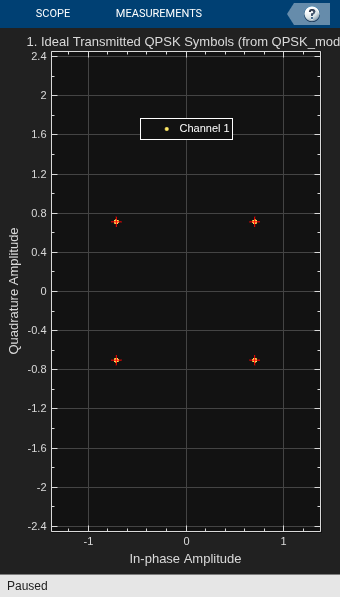

% ==== Generate random symbols (e.g., QPSK) ====

data = randi([0 1],1,N);
[I,Q] = QPSK(data);
symbolsComplex = I + 1j*Q;
% PLOT 1: Ideal Transmitted Symbols
constDiag1 = comm.ConstellationDiagram(...
    'Title', '1. Ideal Transmitted QPSK Symbols (from QPSK_mod)', ...
    'ReferenceConstellation', refConstellation, ...
    'ShowLegend', true);
step(constDiag1, symbolsComplex'); 

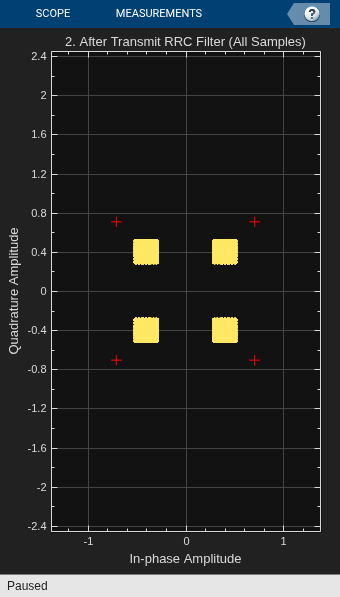


% ==== Upsample symbols ====
I_upsampled = zero_stuffing(I,OSR);
Q_upsampled = zero_stuffing(Q,OSR);

% ==== Apply RRC Filter ====
I_filtered = conv(I_upsampled,h_filter,'same') ;
Q_filtered = conv(Q_upsampled,h_filter,'same') ;

rx_signal =  I_filtered + 1j* Q_filtered ;

% PLOT 2: After Transmit RRC Filter (All Samples)
constDiag2 = comm.ConstellationDiagram(...
    'Title', '2. After Transmit RRC Filter (All Samples)', ...
    'SamplesPerSymbol', OSR, ...
    'ReferenceConstellation', refConstellation);
step(constDiag2, rx_signal');

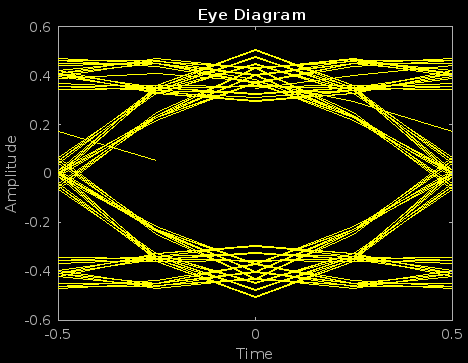



% Ploting eye diagram
eyediagram(I_filtered,OSR)

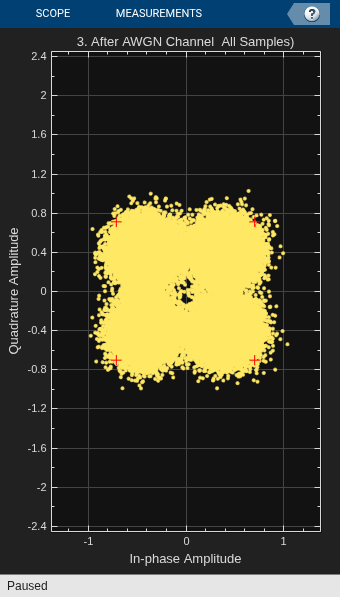

% Adding Noise 
noisy_signal = adding_awgn_noise(rx_signal,SNR);

I_recieved = real(noisy_signal);
I_rx_filtered = conv(I_recieved,h_filter,'same') ;

% PLOT 3: After AWGN Channel (All Samples)
constDiag3 = comm.ConstellationDiagram(...
    'Title', '3. After AWGN Channel  All Samples)', ...
    'SamplesPerSymbol', OSR, ...
    'ReferenceConstellation', refConstellation);
step(constDiag3, noisy_signal');

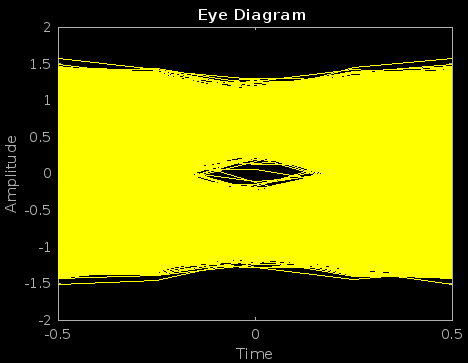



% Ploting eye diagram
figure;
eyediagram(I_rx_filtered,OSR)